clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


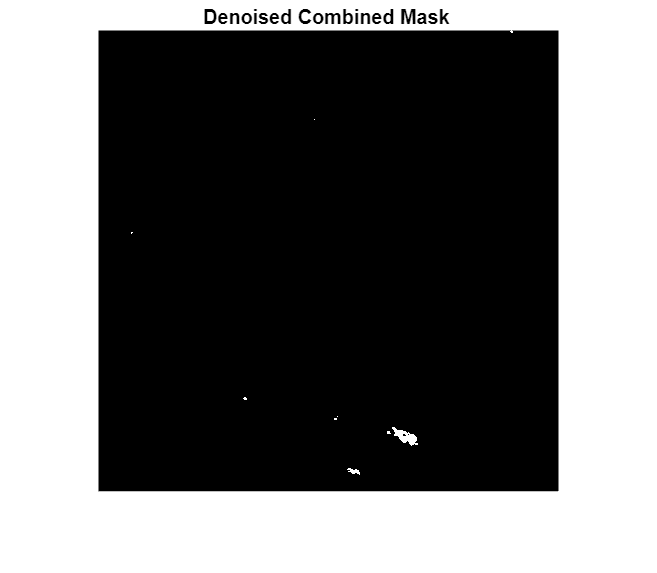

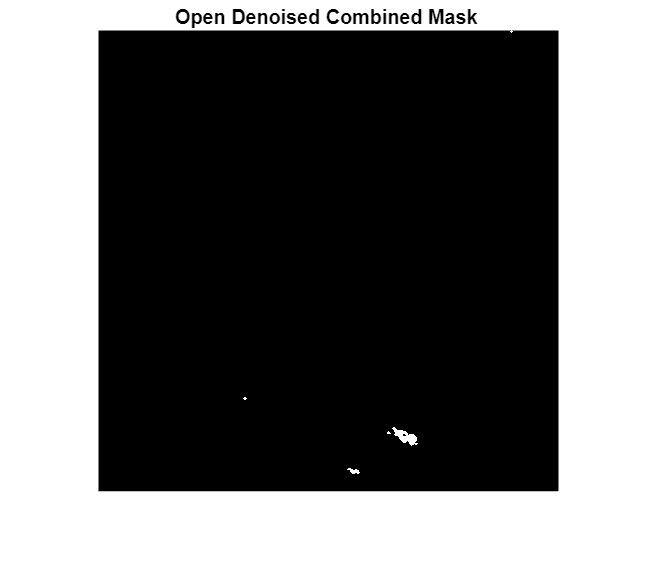

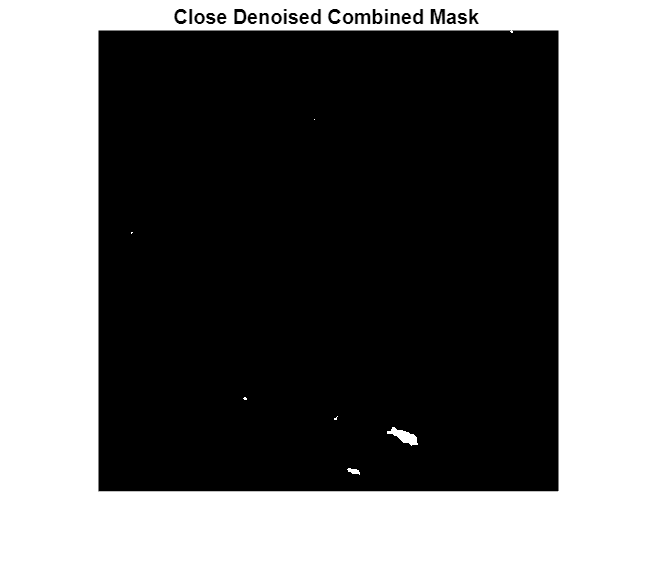

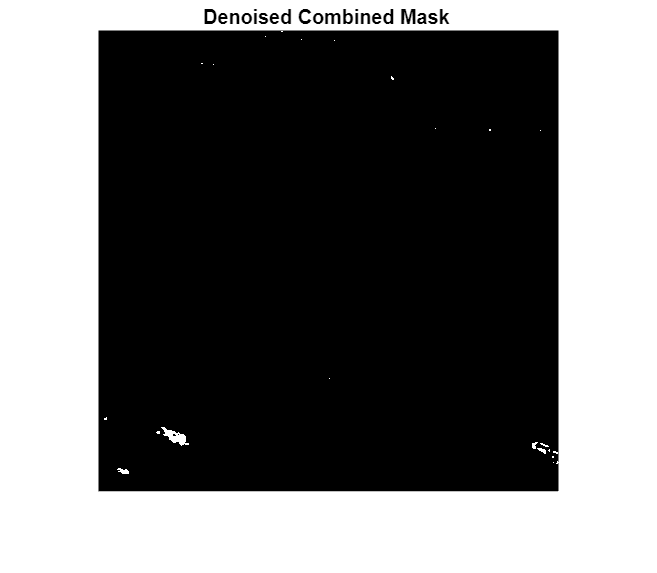

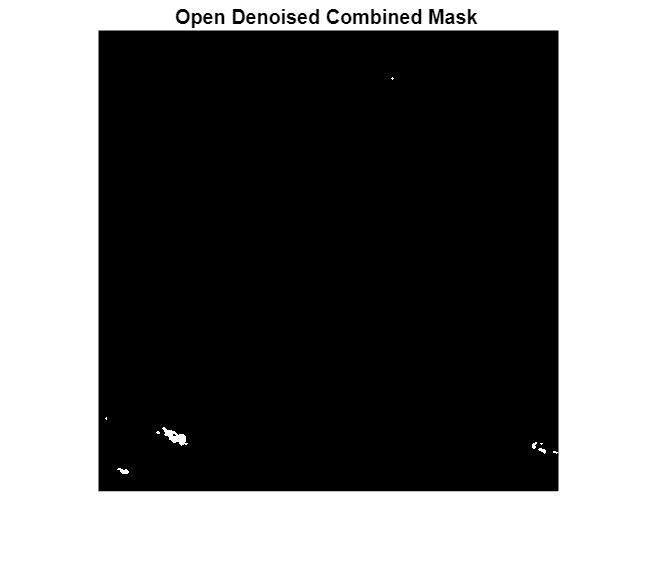

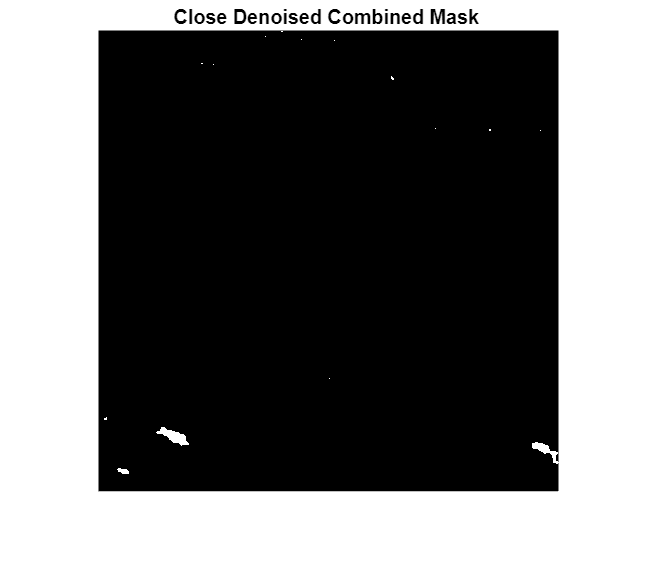

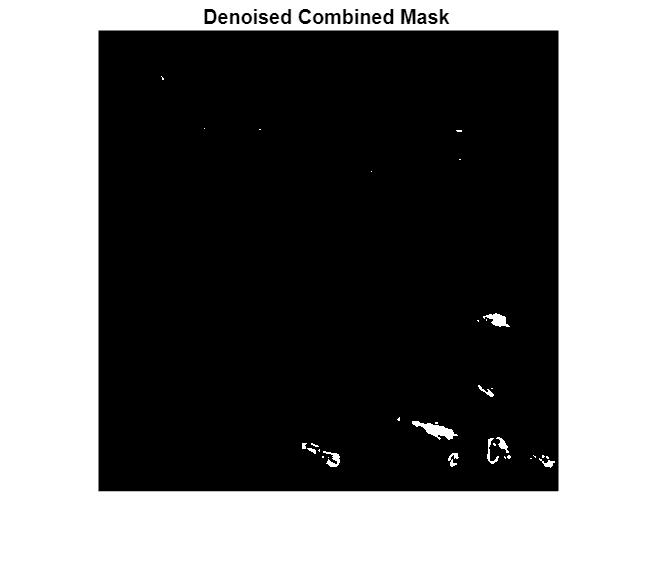

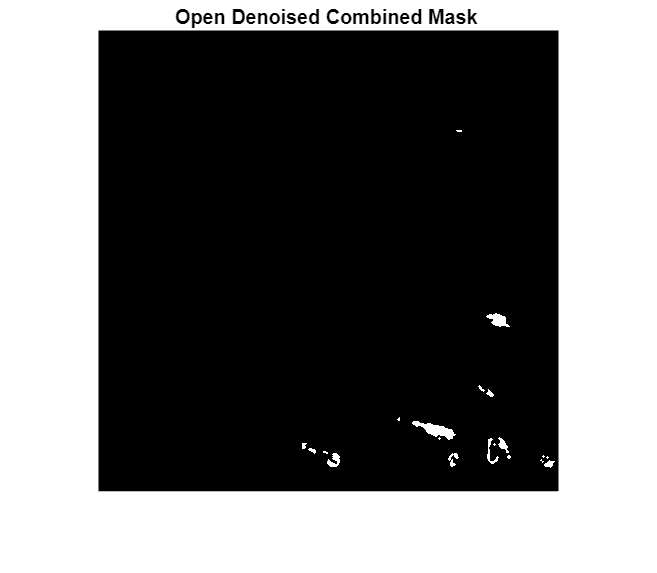


for i=1:3%size(imgs,4)
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    img_hsv = rgb2hsv(img);
    
    % Convert into HSV format and exctract CHs
    R_CH = img(:,:,1); % Red CH
    G_CH = img(:,:,2); % Green CH
    B_CH = img(:,:,3); % Blue CH
    H_CH = img_hsv(:,:,1); % Hue CH
    S_CH = img_hsv(:,:,2); % Saturation CH
    V_CH = img_hsv(:,:,3); % Value CH

    % figure;
    % subplot(2,2,1);
    % imshow(label);
    % subplot(2,2,2);
    % imshow(H_CH);
    % subplot(2,2,3);
    % imshow(S_CH);
    % subplot(2,2,4);
    % imshow(V_CH);
    % sgtitle(sprintf('Img %d',i));

    % figure;
    % histogram(V_CH);
    % sgtitle(sprintf('Img %d',i));   

    % H_mask_imadjust = imadjust(H_mask);
    % H_mask_adapthisteq = adapthisteq(H_mask);
    
    % figure;
    % imshow(label);
    % title(sprintf('Img %d',i));
    % figure;
    % subplot(2,2,1);
    % imshow(H_mask);
    % title(sprintf('H_mask %d',i));
    % subplot(2,2,2);
    % imshow(H_mask_imadjust);
    % title(sprintf('H Mask Imadjust %d',i));
    % subplot(2,2,3);
    % imshow(H_mask_histeq);
    % title(sprintf('H Mask Histeq %d',i));
    % subplot(2,2,4);
    % imshow(H_mask_adapthisteq);
    % title(sprintf('H Mask Adapthisteq %d',i));
    
    % figure;
    % subplot(2,3,1);
    % imshow(label);
    % subplot(2,3,2);
    % imshow(H_CH);
    % subplot(2,3,3);
    % imshow(H_mask);
    % subplot(2,2,3);
    % imshow(H_mask);
    % title(sprintf('Img %d',i));

    % Reduce contrast
    H_mask = H_CH;
    H_mask = histeq(H_mask);
    H_thresh = 0.85;
    H_mask_bin = H_mask >= H_thresh;
    %H_mask_bin_close = imopen(H_mask_bin, strel('disk', 3)); % Remove small noise
    V_mask = V_CH;
    V_mask = histeq(V_mask);
    V_thresh = 0.85;
    V_mask_bin = V_mask >= V_thresh;
    %V_mask_bin_close = imopen(V_mask_bin, strel('disk', 3)); % Remove small noise
    
    % figure;
    % imshow(label);
    % figure;
    % subplot(2,2,1);
    % imshow(H_CH);
    % subplot(2,2,2);
    % imshow(H_mask);
    % subplot(2,2,3);
    % imshow(H_mask_bin);
    % subplot(2,2,4);
    % imshow(H_mask_bin_close);

    % figure;
    % subplot(2,2,1);
    % imshow(label);
    % title('Label');
    % subplot(2,2,2);
    % imshow(H_mask_bin);
    % title('H Mask');
    % subplot(2,2,3);
    % imshow(V_mask_bin);
    % title('V Mask');
    % subplot(2,2,4);
    % imshow(Mask_HV);
    % title('Combined Mask');
    % sgtitle(sprintf('Img %d',i));

    % Match areas where landlsides could be
    Mask_HV = H_mask_bin & V_mask_bin;
    % Remove very small patches by assuming they are like 'salt and pepper' noise
    Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
    Mask_HV_denoised_closed = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
    Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 1)); % Remove small noise
    % figure; - for CLOSED
    % subplot(2,2,1);
    % imshow(label);
    % title('Label');
    % subplot(2,2,2);
    % imshow(Mask_HV);
    % title('Combined Mask');
    % subplot(2,2,3);
    % imshow(Mask_HV_denoised);
    % title('Denoised Combined Mask');
    % subplot(2,2,4);
    % imshow(Mask_HV_denoised_open);
    % title('MM Denoised Combined Mask');
    % sgtitle(sprintf('Img %d',i));

    % figure; - for OPEN
    % imshow(Mask_HV_denoised);
    % title('Denoised Combined Mask ',i);
    % figure;
    % imshow(Mask_HV_denoised_open);
    % title('Open Denoised Combined Mask ',i);
    % figure;
    % imshow(Mask_HV_denoised_closed);
    % title('Close Denoised Combined Mask ',i);
    
    % figure;
    % subplot(1,2,1);
    % imshow(label);
    % title('Label');
    % subplot(1,2,2);
    % imshow(Mask_HV_denoised);
    % title('Denoised Combined Mask');
    % sgtitle(sprintf('Img %d',i));
end

## V1 - Using Open

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,length(imgs_files),'uint8');
labels = zeros(512,512,3,length(imgs_files),'uint8');
for i=1:length(imgs_files)
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =          512         512           3        1486


size(labels)

ans =          512         512           3        1486



t1 = datetime('now');
accur = zeros(1,size(imgs,4))

accur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


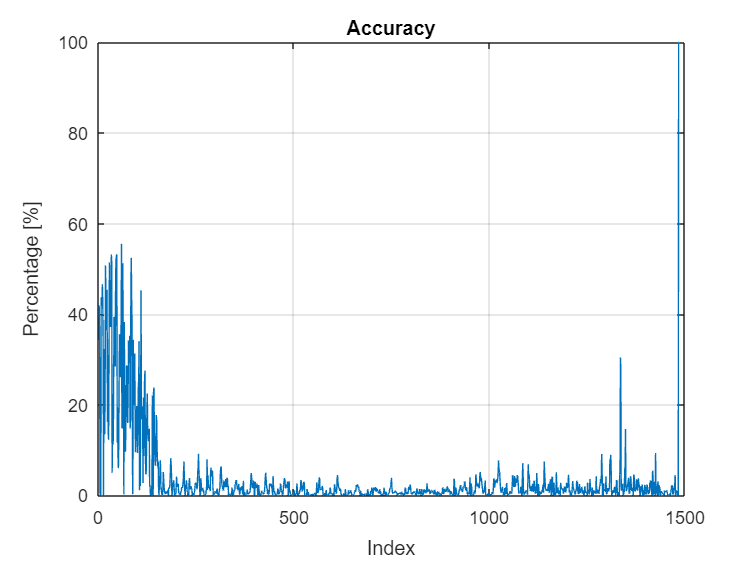

for i=1:size(imgs,4)
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    img_hsv = rgb2hsv(img);
    
    % Super sample - Use interpolation to increase res
    scale_factor = 2;
    img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best

    % Convert into HSV format and exctract CHs
    R_CH = img(:,:,1); % Red CH
    G_CH = img(:,:,2); % Green CH
    B_CH = img(:,:,3); % Blue CH
    H_CH = img_hsv(:,:,1); % Hue CH
    S_CH = img_hsv(:,:,2); % Saturation CH
    V_CH = img_hsv(:,:,3); % Value CH

    % Reduce contrast
    H_mask = H_CH;
    H_mask = histeq(H_mask);
    H_thresh = 0.85;
    H_mask_bin = H_mask >= H_thresh;
    V_mask = V_CH;
    V_mask = histeq(V_mask);
    V_thresh = 0.85;
    V_mask_bin = V_mask >= V_thresh;

    % Match areas where landlsides could be
    Mask_HV = H_mask_bin & V_mask_bin;
    
    % Remove very small patches by assuming they are like 'salt and pepper' noise
    Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
    Mask_HV_denoised_open = imopen(Mask_HV_denoised, strel('disk', 1)); % Remove small noise
    Mask_HV_denoised_open = imresize(Mask_HV_denoised_open, [size(img,1), size(img,2)], 'nearest');
    
    % figure;
    % subplot(2,2,1);
    % imshow(label);
    % title('Label');
    % subplot(2,2,2);
    % imshow(H_mask_bin);
    % title('H Mask');
    % subplot(2,2,3);
    % imshow(V_mask_bin);
    % title('V Mask');
    % subplot(2,2,4);
    % imshow(Mask_HV);
    % title('Combined Mask');
    % sgtitle(sprintf('Img %d',i));
    
    % figure;
    % subplot(1,2,1);
    % imshow(label);
    % title('Label');
    % % subplot(1,2,2);
    % % imshow(Mask_HV);
    % % title('Combined Mask');
    % % subplot(2,2,3);
    % % imshow(Mask_HV_denoised);
    % % title('Denoised Combined Mask');
    % subplot(1,2,2);
    % imshow(Mask_HV_denoised_open);
    % title('MM Denoised Combined Mask');
    % sgtitle(sprintf('Img %d',i));

    
    [x_lbl, y_lbl] = find(label);
    count = 0;
    for k=1:length(x_lbl)
        if(Mask_HV_denoised_open(x_lbl(k),y_lbl(k))) == 1
            count = count + 1; % Correctly identified landlside - should also do one for the non-landslide
        end
    end
    similarity = count / length(x_lbl) * 100;
    accur(1,i) = similarity;
    imwrite(Mask_HV_denoised_open,sprintf('C:/Users/andre/Year5/EE581/Project/Datasets/Full_CAS/Hokkaido Iburi-Tobu/Pred_HSV_SS/Pred%d.jpg',i));
end
figure;
plot(1:length(accur),accur);
xlabel('Index');
ylabel('Percentage [%]');
title('Accuracy')
grid on;

t2 = datetime('now');
dt = between(t1,t2)

dt = calendarDuration
   0h 4m 20.65s


## V1 - Using Open

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,length(imgs_files),'uint8');
labels = zeros(512,512,3,length(imgs_files),'uint8');
for i=1:length(imgs_files)
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =          512         512           3        1486


size(labels)

ans =          512         512           3        1486



t1 = datetime('now');
accur = zeros(1,size(imgs,4))

accur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


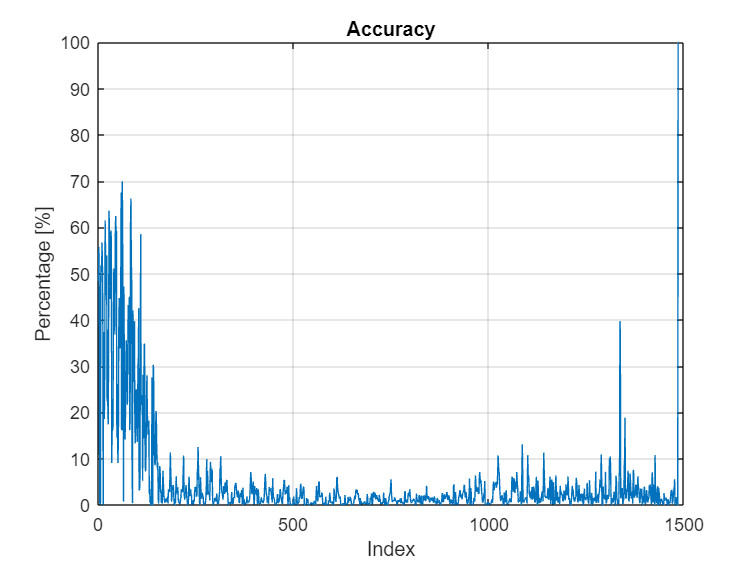

for i=1:size(imgs,4)
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    img_hsv = rgb2hsv(img);
    
    % Super sample - Use interpolation to increase res
    scale_factor = 2;
    img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best

    % Convert into HSV format and exctract CHs
    R_CH = img(:,:,1); % Red CH
    G_CH = img(:,:,2); % Green CH
    B_CH = img(:,:,3); % Blue CH
    H_CH = img_hsv(:,:,1); % Hue CH
    S_CH = img_hsv(:,:,2); % Saturation CH
    V_CH = img_hsv(:,:,3); % Value CH

    % Reduce contrast
    H_mask = H_CH;
    H_mask = histeq(H_mask);
    H_thresh = 0.85;
    H_mask_bin = H_mask >= H_thresh;
    V_mask = V_CH;
    V_mask = histeq(V_mask);
    V_thresh = 0.85;
    V_mask_bin = V_mask >= V_thresh;

    % Match areas where landlsides could be
    Mask_HV = H_mask_bin & V_mask_bin;
    
    % Remove very small patches by assuming they are like 'salt and pepper' noise
    Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
    Mask_HV_denoised_closed = imclose(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
    Mask_HV_denoised_closed = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
    
    % figure;
    % subplot(2,2,1);
    % imshow(label);
    % title('Label');
    % subplot(2,2,2);
    % imshow(H_mask_bin);
    % title('H Mask');
    % subplot(2,2,3);
    % imshow(V_mask_bin);
    % title('V Mask');
    % subplot(2,2,4);
    % imshow(Mask_HV);
    % title('Combined Mask');
    % sgtitle(sprintf('Img %d',i));
    
    % figure;
    % subplot(1,2,1);
    % imshow(label);
    % title('Label');
    % % subplot(1,2,2);
    % % imshow(Mask_HV);
    % % title('Combined Mask');
    % % subplot(2,2,3);
    % % imshow(Mask_HV_denoised);
    % % title('Denoised Combined Mask');
    % subplot(1,2,2);
    % imshow(Mask_HV_denoised_open);
    % title('MM Denoised Combined Mask');
    % sgtitle(sprintf('Img %d',i));

    
    [x_lbl, y_lbl] = find(label);
    count = 0;
    for k=1:length(x_lbl)
        if(Mask_HV_denoised_closed(x_lbl(k),y_lbl(k))) == 1
            count = count + 1; % Correctly identified landlside - should also do one for the non-landslide
        end
    end
    similarity = count / length(x_lbl) * 100;
    accur(1,i) = similarity;
    imwrite(Mask_HV_denoised_closed,sprintf('C:/Users/andre/Year5/EE581/Project/Datasets/Full_CAS/Hokkaido Iburi-Tobu/Pred_HSV_SS2/Pred%d.jpg',i));
end
figure;
plot(1:length(accur),accur);
xlabel('Index');
ylabel('Percentage [%]');
title('Accuracy')
grid on;

t2 = datetime('now');
dt = between(t1,t2)

dt = calendarDuration
   0h 1m 57.358s
